% Generating HRTFs over all positions, converts each one into HRIR at that
% position 
amt_start;

 
****************************************************************************
 
The Auditory Modeling Toolbox (AMT) version 1.5.0.
Brought to you by the AMT Team. See http://amtoolbox.org for more information.
 
****************************************************************************
Starting packages and toolboxes:
* Deep Learning Toolbox: Found.
* Signal Processing Toolbox: Found.
* Statistics and Machine Learning Toolbox: Found.
* Python Environment: Python 3.8.0.
* LTFAT: LTFAT version 2.5.0 (for AMT). Copyright 2005-2018 Peter L. Søndergaard. For help, please type "ltfathelp". LTFAT is using the script language backend.
* SOFA: SOFA Toolbox for Matlab/Octave 2.2.0. Copyright: Acoustics Research Institute.
* SFS: Toolbox version 2.5.0 loaded
* CIRCSTAT: Circular statistics toolbox found.
* BINAURALSH: BinauralSH toolbox loaded.
 
****************************************************************************
 
Internal configuration:
  
  Auxiliary data (local): C:\Users\simon\On

SHT_dir = "C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\SHTCNN\C1_sim_Out_pp1_45\result_00.mat";
load(SHT_dir)
gen1 = gen_sht_array;

%SHT2 = "C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\SHTCNN\C1Out_\result_00.mat";
%load(SHT2);
load("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\SHTCNN\Output all feats, sub 92\sht_preprocessing\HUTUBS_matrix_simulated.mat")

addpath("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\SHTCNN\Output all feats, sub 92\sht_preprocessing\SHtools")
addpath 'C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\SHTCNN\Output all feats, sub 92\sht_preprocessing'

% Sofa Details
s = sofaconvention("SimpleFreeFieldHRIR");
M = 440

M = 440

N = 300

N = 300

R = 2

R = 2

E = 1

E = 1

IRs = zeros(M,R,N);

% For loop to populate TFs using locations given by HUTUBS datast
extf = sofaread("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\pp1_HRIRs_measured.sofa")

extf =   audio.sofa.SimpleFreeFieldHRIR with properties:

            Numerator: [440×2×256 double]
                Delay: [0 0]
         SamplingRate: 44100
    SamplingRateUnits: "hertz"

  Show all properties


pos = extf.SourcePosition(:,1:2)

pos =      0    90
     0    80
    60    80
   120    80
   180    80
   240    80
   300    80
     0    70
    24    70
    48    70


T = readmatrix("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\SHTCNN\Output all feats, sub 92\sht_preprocessing\freqbins.csv");
freqs = T(freq_logind);
rec_tf1 = HRTF_SHT_recreat(gen1(:,:,1).', 0, 0);
rec_tf2 = HRTF_SHT_recreat(gen_sht_array(:,:,1).', 0, 0);

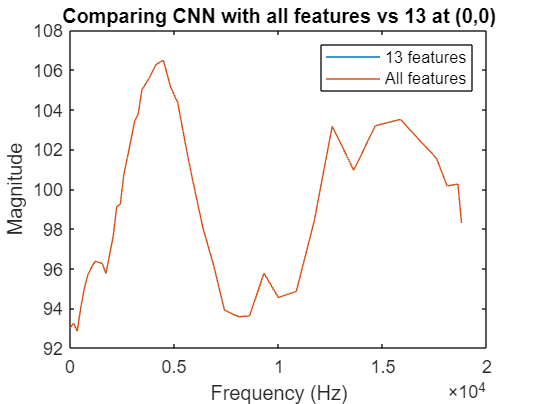

plot(freqs, rec_tf1, freqs, rec_tf2)

xlabel("Frequency (Hz)")
ylabel("Magnitude")
title("Comparing CNN with all features vs 13 at (0,0)")
legend('13 features','All features')

freqs(end)

ans = 1.8777e+04

% Goal is 128 frequency bins, upto freqs(end)
Nf = 127;
step = freqs(end) / Nf;

infreqs = 0:step:44100/2;

%intf = zeros(1,150);


intf = interp1(freqs, rec_tf1, infreqs(1:Nf+1));

%Zero padding instead of going up to final freqs
intf(Nf+1:length(infreqs)) = 0;

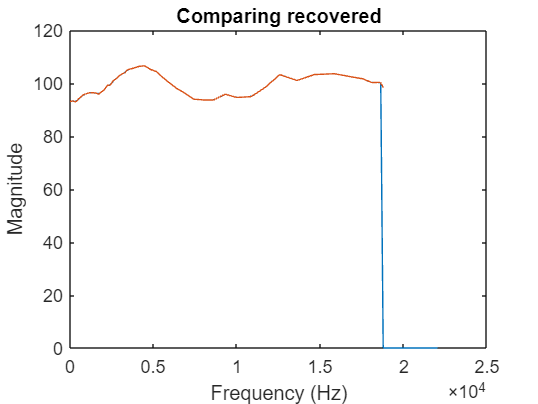

plot(infreqs, intf, freqs, rec_tf1)
%semilogx(infreqs, intf, freqs, rec_tf1)
xlabel("Frequency (Hz)")
ylabel("Magnitude")
title("Comparing recovered")

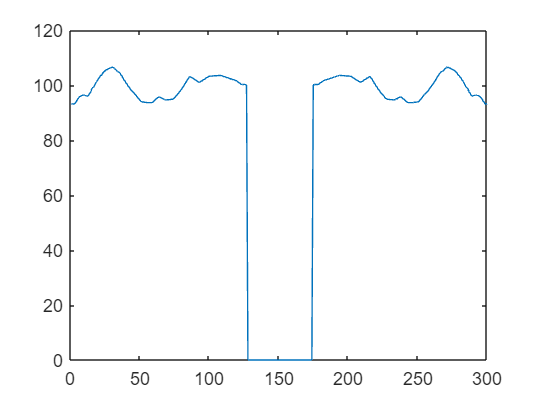

% To get an ft of length 256, the values of the recovered ft must be
% reflected and concatenated with the first 
fft4real = [intf,intf(end), fliplr(conj(intf(:,2:end)))];
plot(fft4real)

Y1 = intf;

Y2 = [Y1(1) Y1(2:end)/2 fliplr(conj(Y1(2:end)))/2];

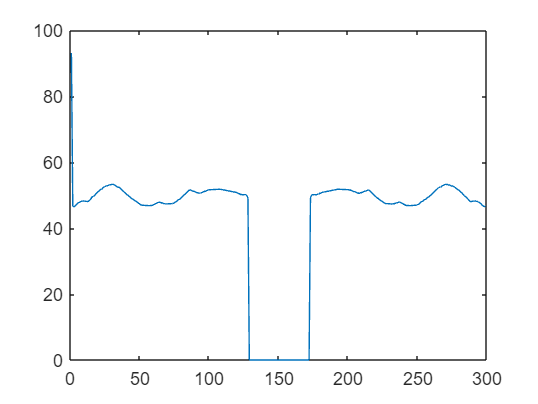

plot(Y2)

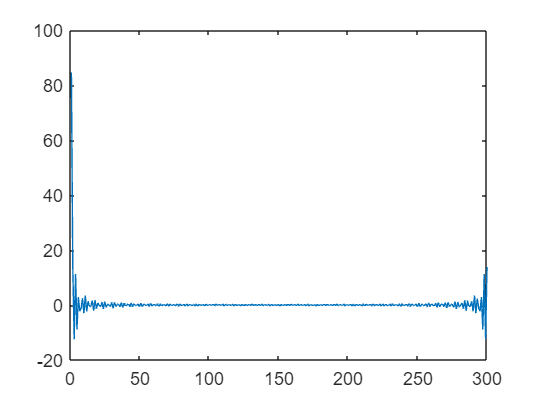

IR = ifft(fft4real);
plot(IR)

round(2*freqs(end))

ans = 34109

4.41e+4 / (2*freqs(end))

ans = 1.2929

IRre = 1×331 single row vector
   95.4185   26.8990  -16.3053   10.7186   -3.2947   -5.0180    1.6127   -2.6827    1.0840   -0.2462   -0.3345    1.0371   -0.1529   -0.1506    0.0421    0.1308    0.0847   -0.0248    0.0184    0.1805    0.1173   -0.0190    0.0893    0.1625    0.0367    0.0038    0.0563    0.0193   -0.0058    0.0184    0.0055   -0.0268   -0.0544   -0.0599   -0.0514   -0.0906   -0.1366   -0.0927   -0.0252   -0.0496   -0.0951   -0.0765   -0.0506   -0.0530   -0.0516   -0.0377   -0.0253   -0.0346   -0.0518   -0.0415


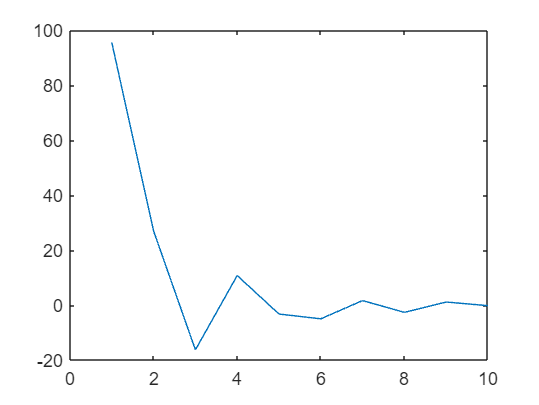

plot(IRre(1:10))

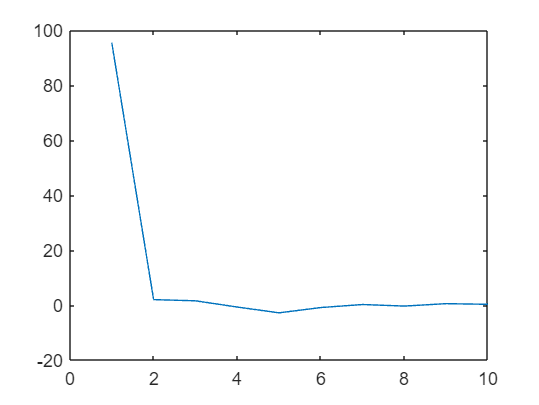

plot(IR(1:10))

tf2 = abs(fft(IR))

tf2 =    93.0128   93.2087   92.9616   93.5287   94.4524   95.2085   95.7581   96.0782   96.3204   96.3232   96.2760   96.0271   96.0230   96.8225   97.6054   98.9101   99.1934  100.1215  101.1293  101.8828  102.6585  103.4210  103.7200  104.6650  105.1579  105.4098  105.6803  105.9831  106.2780  106.3644  106.4507  106.0695  105.4939  105.0070  104.6670  104.3042  103.4693  102.6344  101.8353  101.0504  100.2908   99.5715   98.8522   98.1329   97.5705   97.0276   96.4847   95.9019   95.2579   94.6138


plot(infreqs,tf2(1:128),infreqs,intf)

Error using plot
Vectors must be the same length.

% All together now!

% Sofa Details
s = sofaconvention("SimpleFreeFieldHRIR");
M = 440

M = 440

N = 300

N = 300

R = 2

R = 2

E = 1

E = 1


IRs = zeros(M,R,N);

extf = sofaread("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\pp1_HRIRs_measured.sofa")

extf =   audio.sofa.SimpleFreeFieldHRIR with properties:

            Numerator: [440×2×256 double]
                Delay: [0 0]
         SamplingRate: 44100
    SamplingRateUnits: "hertz"

  Show all properties


pos = extf.SourcePosition(:,1:2)

pos =      0    90
     0    80
    60    80
   120    80
   180    80
   240    80
   300    80
     0    70
    24    70
    48    70



T = readmatrix("C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\SHTCNN\Output all feats, sub 92\sht_preprocessing\freqbins.csv");
freqs = T(freq_logind);

Nf = 127;
step = freqs(end) / Nf;


for j = 1:2
    for i=1:M
        tf = HRTF_SHT_recreat(gen_sht_array(:,:,j).', pos(i,1), pos(i,2));

        intf = interp1(freqs, tf, infreqs(1:Nf+1));
        intf(Nf+1:length(infreqs)) = 0;
        intfsym = [intf,intf(end), fliplr(conj(intf(:,2:end)))];

        IRs(i,j,:) = ifft(intfsym);

    end
end

% Saving SOFA file
s.Numerator = IRs;
s.ListenerViewType = extf.ListenerViewType;
s.ListenerView = extf.ListenerView;
s.ListenerPosition = extf.ListenerPosition;
s.ReceiverPosition = extf.ReceiverPosition;
s.SourcePosition = extf.SourcePosition

s =   audio.sofa.SimpleFreeFieldHRIR with properties:

            Numerator: [440×2×300 double]
                Delay: [0 0]
         SamplingRate: 48000
    SamplingRateUnits: "hertz"

  Show all properties


s.SamplingRate = 2*infreqs(end);
s.Title = "Subject 1 HRIR gen v3 ";
s.Comment = "This SOFA file contains the reconstrucred HRIRs of Subject 1 with zero padding up to 44100Hz/2";

fn = "C:\Users\simon\OneDrive\Documents\Senior Thesis\Code\Datasets\HUTUBS\simu\Subj_gen" + "\Sub1_45v2.sofa";
sofawrite(fn,s);